# Creat Grid Map

`@author: Winter`

`@update: 2023.1.29`

## function import

addpath(genpath("env\"));
addpath(genpath("Users/jonas/Desktop/Studie/h25/IN5060/matlab_motion_planning/utils/env\"));

## map A

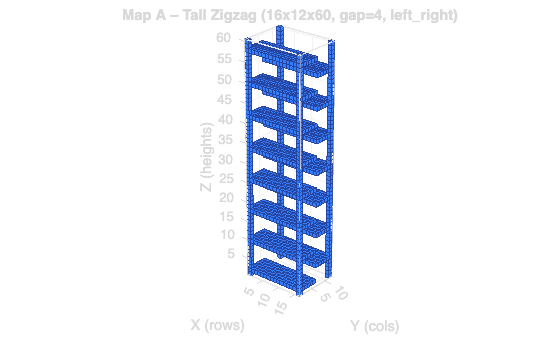

% utils/env/generate_mapA_tall_zigzag.m
% Map A (drone test): tall, narrow, with alternating half-floors.

clear; clc; close all;

% ---------- SIZE (tall & narrow) ----------
rows = 16; cols = 12; heights = 60;         % tweak as you like
map_size = [rows, cols, heights];

% ---------- GEOMETRY PARAMS ----------
floorGap        = 4;     % vertical spacing (voxels) between floors
floorThickness  = 1;     % thickness of each floor (in voxels)
halfMode        = "left_right";  % "left_right" or "front_back"
inset           = 0;     % shrink floors inward from walls (0 = flush)
useCornerCols   = true;  % 4 corner columns up the whole height

obstacle = [];

%% (A) Corner columns (for structure & visual anchors)
if useCornerCols
    rC = [1, rows]; cC = [1, cols]; zC = 1:heights;
    [RC, CC, ZC] = ndgrid(rC, cC, zC);
    obstacle = [obstacle; sub2ind(map_size, RC(:), CC(:), ZC(:))];
end

%% (B) Zig-zag floors: at z = 2, 2+floorGap, ...
zList = 2:floorGap:(heights-1);
for k = 1:numel(zList)
    z0 = zList(k);
    zPlanes = z0 : min(z0+floorThickness-1, heights);   % thickness support

    % Floor mask for one z-plane
    slab = false(rows, cols);
    switch halfMode
        case "left_right"
            midc = floor(cols/2);
            if mod(k,2)==1      % odd floors: LEFT half present
                cRange = (1+inset) : max(midc-inset, 1);
                rRange = (1+inset) : (rows-inset);
            else                % even floors: RIGHT half present
                cRange = min(midc+1+inset, cols) : (cols-inset);
                rRange = (1+inset) : (rows-inset);
            end
        case "front_back"
            midr = floor(rows/2);
            if mod(k,2)==1      % odd floors: FRONT (top) half present
                rRange = (1+inset) : max(midr-inset, 1);
                cRange = (1+inset) : (cols-inset);
            else                % even floors: BACK (bottom) half present
                rRange = min(midr+1+inset, rows) : (rows-inset);
                cRange = (1+inset) : (cols-inset);
            end
        otherwise
            error('halfMode must be "left_right" or "front_back".');
    end

    % Guard empty ranges when very small dims/inset
    if ~isempty(rRange) && ~isempty(cRange)
        slab(rRange, cRange) = true;
    end

    % Add every plane in the thickness stack
    for z = zPlanes
        [R, C, Z] = ndgrid(1:rows, 1:cols, z);
        obstacle = [obstacle; sub2ind(map_size, R(slab), C(slab), Z(slab))]; %#ok<AGROW>
    end
end

%% (C) Optional: a small full ground pad to take off (comment out if not wanted)
% [Rg, Cg, Zg] = ndgrid( max(2,rows-3):rows-1, 2:cols-1, 1);
% obstacle = [obstacle; sub2ind(map_size, Rg(:), Cg(:), Zg(:))];

%% Finalize & preview
obstacle = unique(obstacle);
grid_map = generate_grid(map_size, obstacle);

save(sprintf('mapA_tallZigzag_%dx%dx%d_gap%d.mat', rows, cols, heights, floorGap), 'grid_map');
plot_grid_3d(grid_map);
title(sprintf('Map A – Tall Zigzag (%dx%dx%d, gap=%d, %s)', ...
    rows, cols, heights, floorGap, halfMode), 'Interpreter','none');

## map B

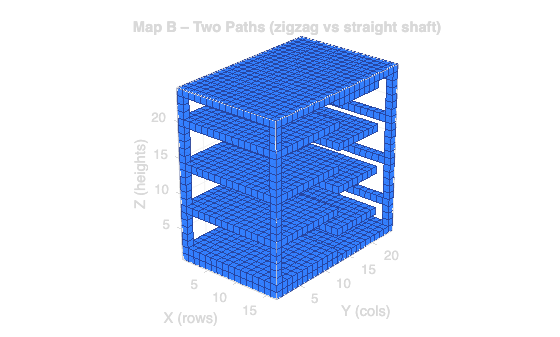

% Map B (two-paths): shorter zigzag vs longer straight shaft
% 16 x 24 x 24 (9216 voxels). Uses generate_grid(map_size, obstacle).

clear; clc; close all;

% ---- size ----
rows = 16; cols = 24; heights = 24;
map_size = [rows, cols, heights];

% ---- parameters ----
floorGap       = 3;   % vertical spacing between floors (voxels)
floorThickness = 1;   % thickness of each floor
useCornerCols  = true;
inset          = 0;   % shrink floors in from walls (0 = flush)

% Straight-path shaft (a vertical corridor) near the right wall
shaftColCenter = cols - 2;      % ~right side
shaftHalfW     = 1;             % shaft width = 2*halfW+1 columns (here: 3 cols)
shaftCols      = max(1, shaftColCenter-shaftHalfW) : min(cols, shaftColCenter+shaftHalfW);

obstacle = [];

%% (A) Ground floor (full slab at z=1) – makes you find holes to go up
[Rg,Cg,Zg] = ndgrid(1:rows, 1:cols, 1);
obstacle = [obstacle; sub2ind(map_size, Rg(:), Cg(:), Zg(:))];

%% (B) Corner columns up the height (optional but looks/behaves like your maps)
if useCornerCols
    rC = [1, rows]; cC = [1, cols]; zC = 1:heights;
    [RC, CC, ZC] = ndgrid(rC, cC, zC);
    obstacle = [obstacle; sub2ind(map_size, RC(:), CC(:), ZC(:))];
end

%% (C) Alternating half-floors ("zigzag floors") every floorGap voxels
% odd floors: LEFT half present (right half missing)
% even floors: RIGHT half present (left half missing)
zList = 2:floorGap:(heights-1);
for k = 1:numel(zList)
    z0 = zList(k);
    zPlanes = z0 : min(z0+floorThickness-1, heights);

    % build a slab mask, then remove half (alternating)
    slab = false(rows, cols);
    midc = floor(cols/2);

    if mod(k,2)==1
        % keep LEFT half (present), remove RIGHT half (missing / open)
        cRange = (1+inset) : max(midc-inset, 1);
        rRange = (1+inset) : (rows-inset);
        slab(rRange, cRange) = true;   % obstacles = present half-floor
    else
        % keep RIGHT half (present), remove LEFT half
        cRange = min(midc+1+inset, cols) : (cols-inset);
        rRange = (1+inset) : (rows-inset);
        slab(rRange, cRange) = true;
    end

    % carve the straight vertical shaft through ANY present half
    slab(:, shaftCols) = false;

    % add slab voxels at each z in the thickness stack
    for z = zPlanes
        [R, C, Z] = ndgrid(1:rows, 1:cols, z);
        obstacle = [obstacle; sub2ind(map_size, R(slab), C(slab), Z(slab))]; %#ok<AGROW>
    end
end

%% (D) Roof at the top (optional; comment out if you want open top)
[Rr,Cr,Zr] = ndgrid(1:rows, 1:cols, heights);
obstacle = [obstacle; sub2ind(map_size, Rr(:), Cr(:), Zr(:))];

%% Finalize & preview
obstacle = unique(obstacle);
grid_map = generate_grid(map_size, obstacle);

save('mapB_twoPaths_16x24x24.mat','grid_map');
plot_grid_3d(grid_map);
title('Map B – Two Paths (zigzag vs straight shaft)');

## map C

clear all;
clc;

% map setting
map_size = [20, 20];
G = 1;    

% obstacle
obs1 = [56, 57, 58, 59, 60, 76, 77, 78, 79, 80];
obs2 = [241, 242, 243, 244, 245, 246, 247, 248, 249, 250, 251, 252, 253, 254, 255, 256, 257, 258];
obs3 = [128, 129, 130, 131, 132, 152, 172, 192, 191, 190, 189, 188];
obs4 = [311, 312, 313, 314, 315, 316, 317, 318, 319, 320];
obs5 = [138, 158, 178, 198, 218, 238, 175, 195, 215, 235, 255];
obs6 = [124, 144, 164, 184, 143, 163, 145, 165];
obs7 = [267, 287, 307, 327, 347, 321, 322, 323, 324];
obs8 = [370, 390, 371, 391, 334, 354, 335, 354, 355, 378, 398];
obstacle = [obs1, obs1- 8, obs1 - 15, obs2, obs3, obs4, obs5, obs6, obs7, obs8];
    
% creat grid
grid_map = generate_grid(map_size, obstacle);

Error using generate_grid (line 14)
Invalid argument at position 1. Value must be a vector with 3 elements.


% save and plot
% save gridmap_20x20_scene3 grid_map
plot_grid(grid_map);

## map D

clear all;
clc;

% map setting
map_size = [20, 20];
G = 1; 

% obstacle
obs1 = 81:88;
obs2 = 90:100;
obs3 = 270:277;
obs4 = [290, 310, 350, 370, 390];

obstacle = [obs1, obs2, obs1 + 20, obs2 + 20, obs1 + 40, obs2 + 40, obs1 + 60, obs2 + 60, obs1 + 80, obs2 + 80, ...
    obs1 + 100, obs2 + 100, obs3, obs4];

% creat grid
grid_map = generate_grid(map_size, obstacle);

% save and plot
% save gridmap_20x20_scene4 grid_map
plot_grid(grid_map);

## map E

clear all;
clc;

% map setting
map_size = [20, 30, 30];
G = 1;

% obstacle
obs0 = [1:map_size(1), ... 
        map_size(1):map_size(1):map_size(1) * map_size(2), ...
        1:map_size(1):(map_size(1) - 1) * map_size(2), ...
        map_size(1) * (map_size(2) - 1):map_size(1) * map_size(2)];
obs1 = [63, 83, 103, 123, 143, 163, 183, 203, 223, 243, 263, 124, 125, 126, 127];
obs2 = [46, 47, 48, 49, 50, 70, 90, 110, 130, 150, 170, 190, 210, 230, 250, 270, 269];
obs3 = [73, 74, 55, 75, 95, 56, 76, 96, 77, 78];
obs4 = [253, 254, 235, 255, 275, 236, 256, 276, 257, 258];
obs5 = [352, 372, 392, 412, 432, 452, 472, 492, 512, 532];
obs6 = [435, 416, 436, 417, 437, 438, 455, 456, 476, 457, 477, 458];
obs7 = [363, 364, 365, 366, 367, 383, 403];
obs8 = [446, 447, 448, 449, 466, 467, 468, 469];
obstacle = [obs0, obs1, obs2, obs3, obs4, obs5, obs6, obs7, obs8];




% creat grid
grid_map = generate_grid(map_size, obstacle); 

% save and plot
save gridmap_20x20_scene1 grid_map
plot_grid(grid_map);



clear all;
clc;

% map setting
map_size = [20, 20];
G = 1; 

% obstacle
obs = [62, 63, 82, 83];
obstacle = [];
for i=0:5
    for j=0:5
        obs_ = obs + 60 * i + 3 * j;
        obstacle = [obstacle, obs_];
    end
end
% obstacle = [obs, obs + 60];

% creat grid
grid_map = generate_grid(map_size, obstacle);

% save and plot
% save gridmap_20x20_scene4 grid_map
plot_grid(grid_map);